# 绘制三维曲线

## plot3() & fplot3()

plot(x, y, z)

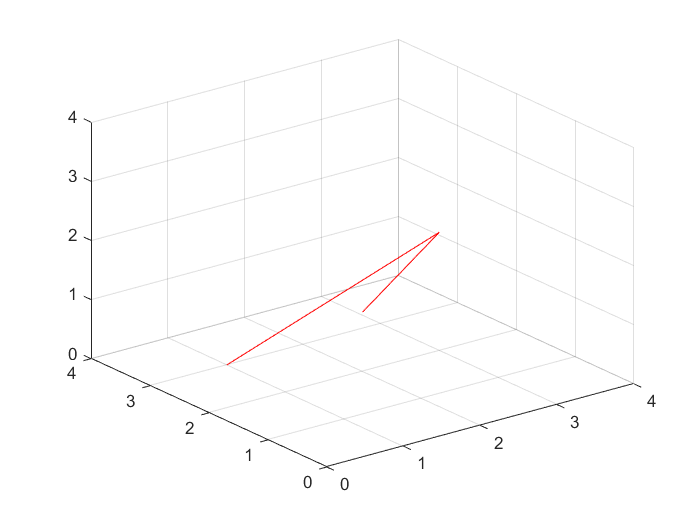

x = [1 3 2];
y = [3 2 2];
z = [0 2 1];
plot3(x, y, z, 'r')
% To show up(1, 3, 0) & (3, 2, 2) & (2, 2, 1)
grid on
axis([0 4 0 4 0 4]);

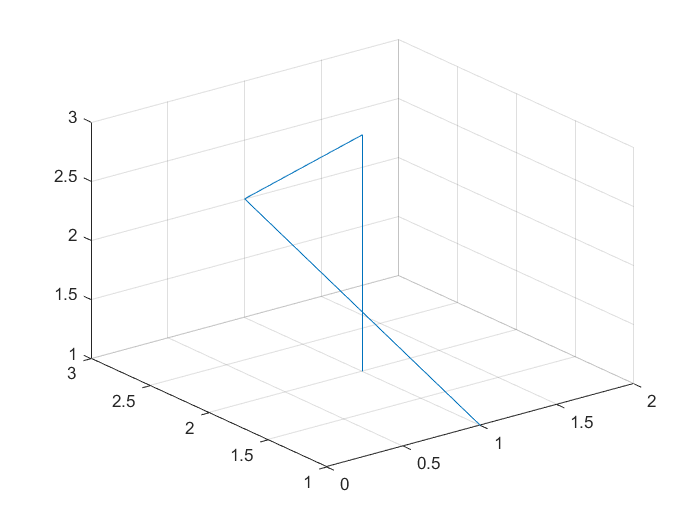

x = [1 1 1 1];
y = [2 2 3 1];
z = [1 3 2 1];
plot3(x, y, z);
grid on

## 通过参数方程

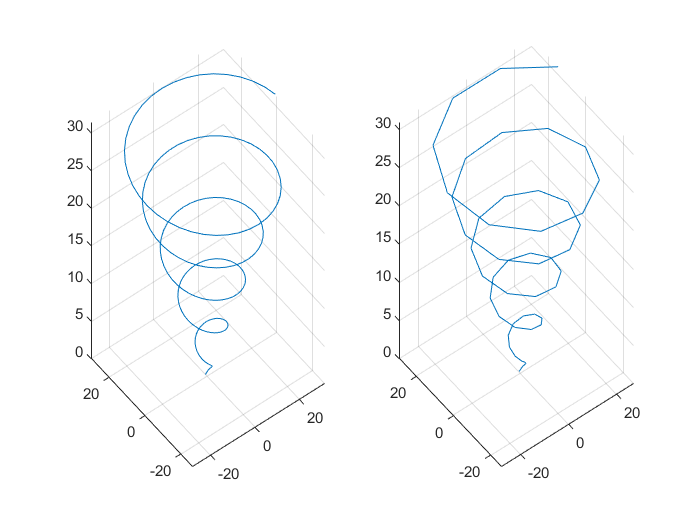

t = linspace(0, 10*pi, 200);
x = sin(t) +t.*cos(t);
y = cos(t)-t.*sin(t);
z = t;

subplot(1, 2, 1)
plot3(x, y, z)
title('Smooth one')
grid on

subplot(1, 2, 2)
plot3(x(1:4:200), y(1:4:200), z(1:4:200))
title
grid on

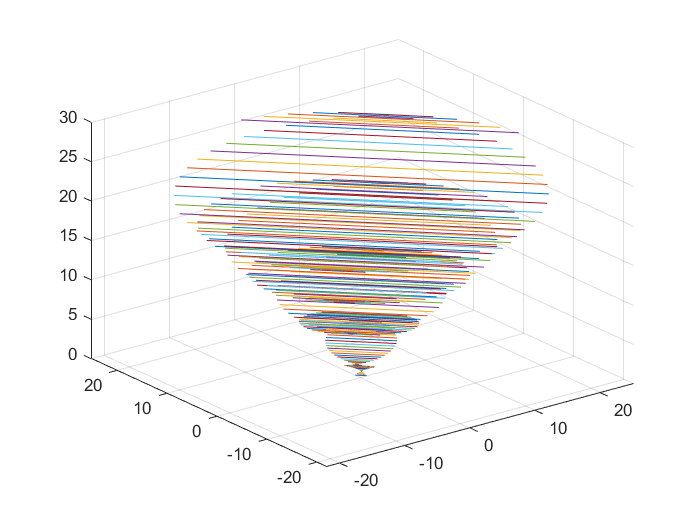

t = linspace(0, 8*pi, 200);
x = [sin(t)+t.*cos(t); cos(t)-t.*sin(t)];
y = [cos(t)-t.*sin(t); sin(t)+t.*cos(t)];
z = [t; t];
plot3(x, y, z);
grid on

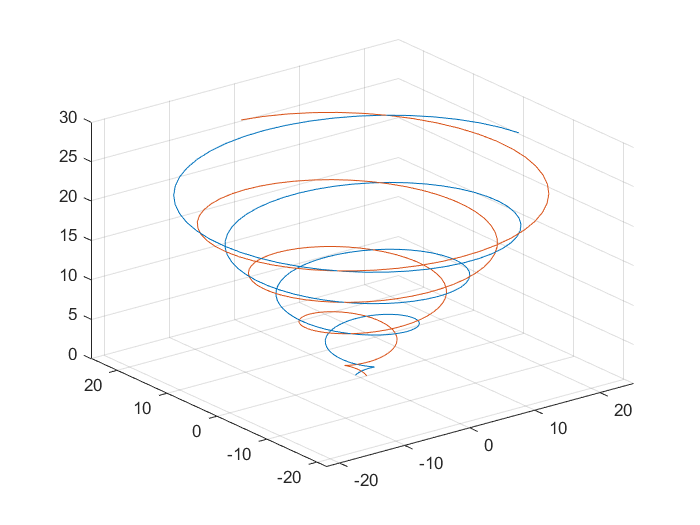

t = linspace(0, 8*pi, 200)';
x = [sin(t)+t.*cos(t) cos(t)-t.*sin(t)];
y = [cos(t)-t.*sin(t) sin(t)+t.*cos(t)];
z = [t t];
plot3(x, y, z);
grid on

## 绘制多条曲线

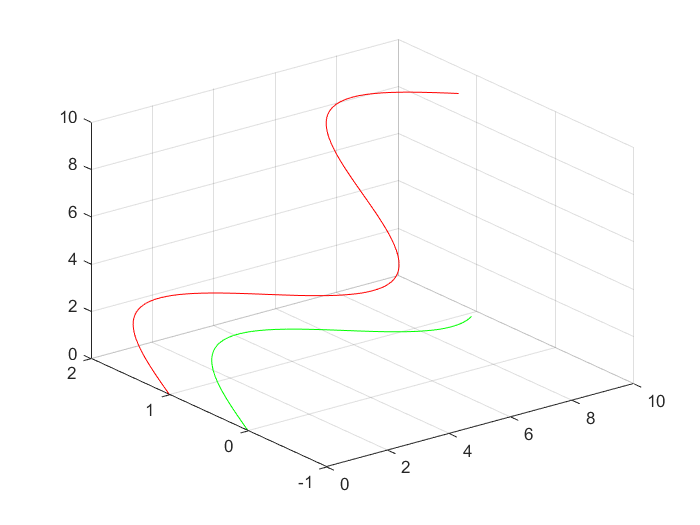

t1 = 0:0.01:1.5*pi;
t2 = 0:0.01:3*pi;
plot3(t1, sin(t1), t1, 'g', t2, sin(t2)+1, t2, 'r')
grid on